# Statistics Viewer

Copyright 2023-2024 The MathWorks, Inc.

The Statistics Viewer will aggregate Simscape model statistics for a given model with its solver configurations. Use it to evaluate model statistics to analyse models containing blocks and investigate the model complexity.

openExample('simscapeelectrical/SinglePhaseGridSolarPVExample')  

Open the Statistics Viewer:

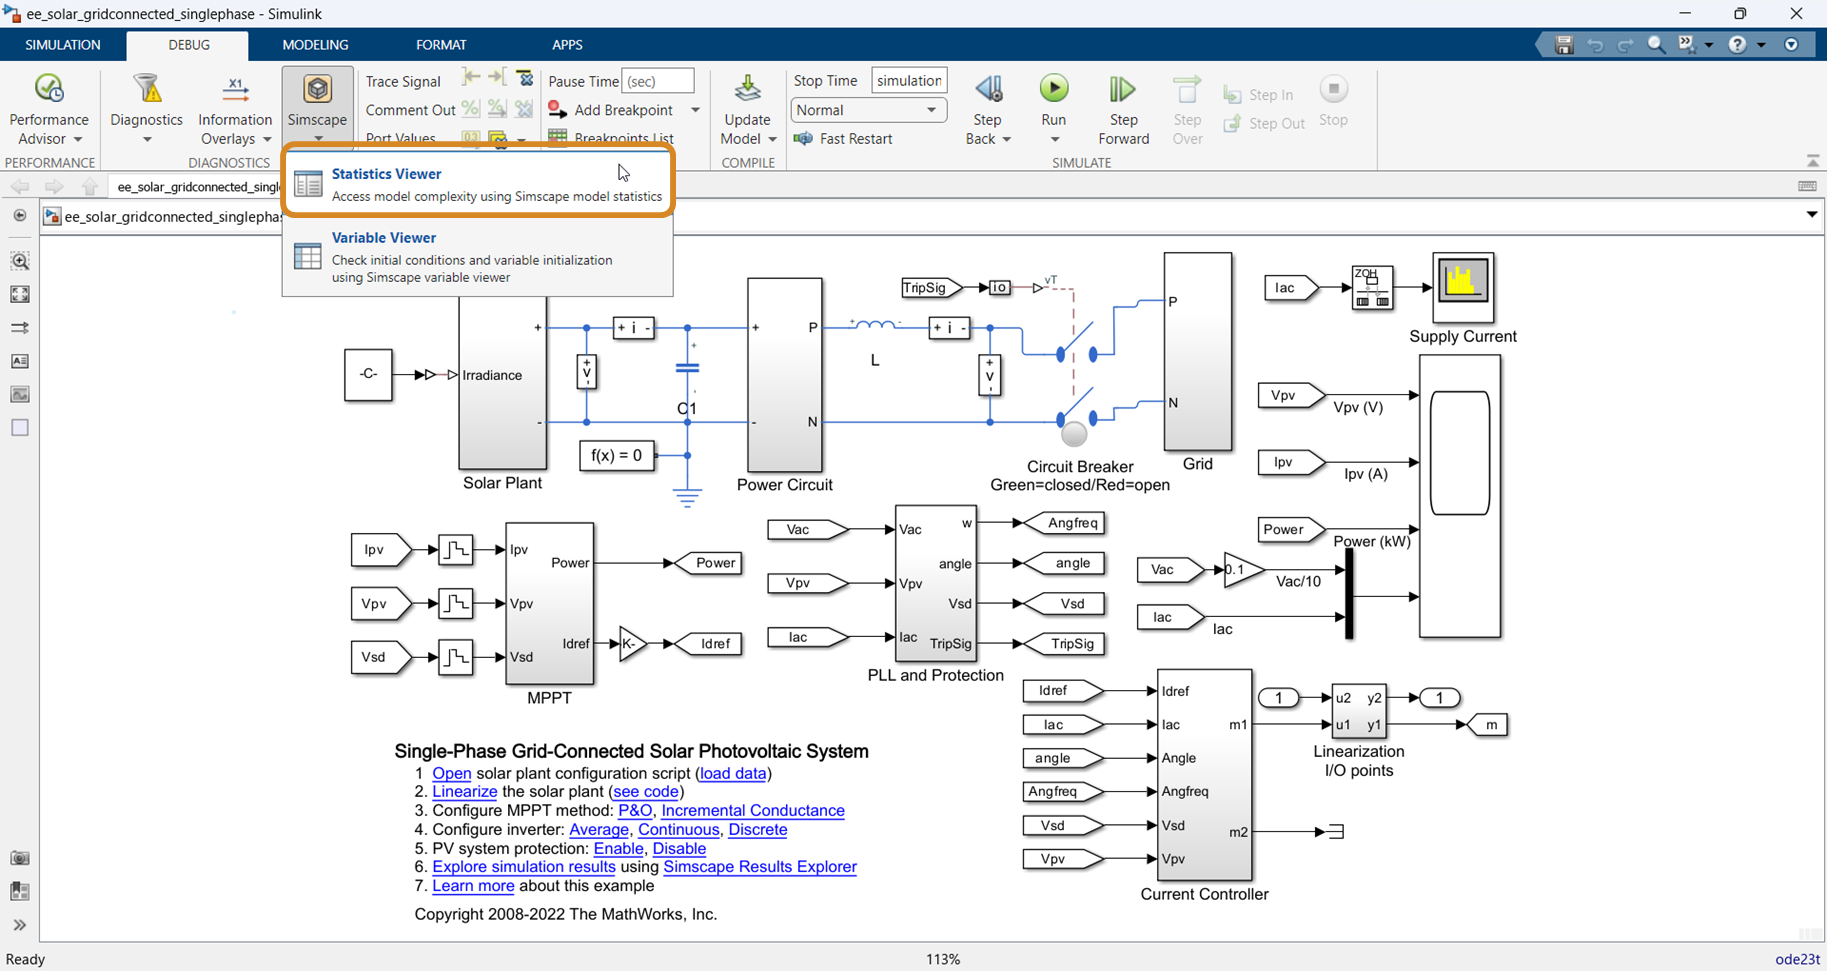

If the model has not been updated, the Statistics Viewer won't be populated with data. Select *Update Model*:

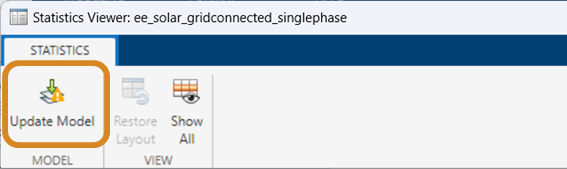

The summary report cummulates the results into up to four different categories: 

- 1-D Physical Systems: Statistics associated with blocks from Simscape, Simscape Electrical, Simscape Driveline, Simscape Fluids

- 3-D Multibody System: Statistics associated with blocks from Simscape Multibody

- Simulink/Simscape Interface: Lists PS-Simulink Converter and Simulink-PS Converter blocks

- 1-D/3D Interface: Statistics associated with connections between 1-D physical system and 2-D Simscape Multibody components

Note: Blocks from the Simscape Electrical Specialized Power System library will not be reported on. 

Here, this is resulting in:

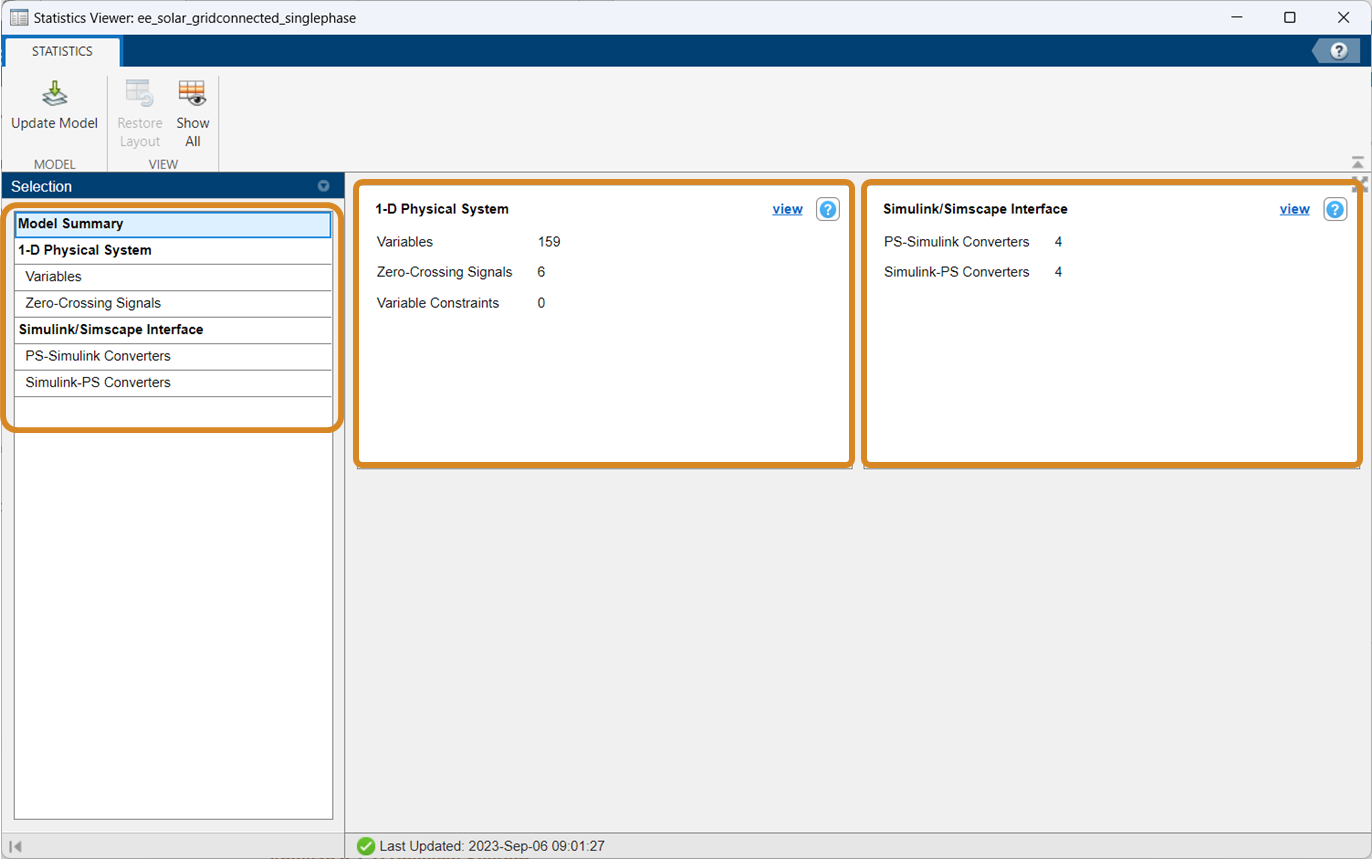

Selecting a item on the left panes, goves more detailed statistics. 

If selecting *Variables* under *1-D Physical System *the report on the right hand side list all variables resulting from the 1-D physical network aftert the equation reduction. These are cetagorized as retained, eliminated and secondary continuous variables and as discrete and secondary discrete variables. [1-D Physical System Statistics](https://www.mathworks.com/help/releases/R2023a/simscape/ug/1-d-physical-system-statistics.html) list more information about the individual variable types. 

Additionally the *Number of zero-crossing signals* and *Variable* *Constraints* can be listed. 

Specifically *Variable* *Constraints* between variables should be removed if possible, the constraints result in high-indes differential algebraic equations and can cause numerical difficulties and simulation slowdown. 

Selecting first a variable category in the top right pane and then a variable path in the bottom right pane allows to directly navigate to the corresponding block in the model: